clc
clear all 
close all

## Preperation

Insert general LS / TD parameters

gamma = 0.9; %discount
samples = 10000; %number of samples considered
states = 3; %number of arbitrary states

Generate dummy data

x_k = randn(states,samples+1); %feature vector at index k
x_k1 = x_k(:, 2:end); %shift of feature vector to index k+1
x_k = x_k(:, 1:end-1); %make both feature vectors equal length
r = ((x_k)'-gamma*(x_k1)')*([2 3 1]') + randn(samples,1); %Generate dummy rewards with a linear function according to TD-rule plus noise. Thus, parameter vector = [2 3 1] is searched.


$$x_k^T w  =\hat{v}(x_{k})=r_{k+1}+\gamma x^T_{k+1}w\\
y_k=r_{k+1}= (x_k^T - \gamma x_{k+1}^T)w
$$


Hence, above $(x_k^T - \gamma x_{k+1}^T)$is one regressor vector in the OLS sense while the reward $r_{k+1}$ is the target. 

## Calculate OLS solution with modified regressor vectors according to TD update rule

Build up OLS regressor matrix


xi = zeros(samples, states); %pre allocate regressor matrix

for ii = 1:samples
    xi(ii,:) = x_k(:,ii)'-gamma*x_k1(:,ii)'; %calculate regressor matrix from feature vectors according to TD update
end

Solve OLS problem straightforward

w_OLS = inv(xi.' * xi)*(xi.' *r) %solve OLS problem with manual matrix inverse

w_OLS =     2.0149
    3.0142
    1.0013


## Calculate parameter vector according to TD fixed point solution (Barto/Sutton)

Calculate A matrix and b vector according to TD fixed point (Barto/Sutton):

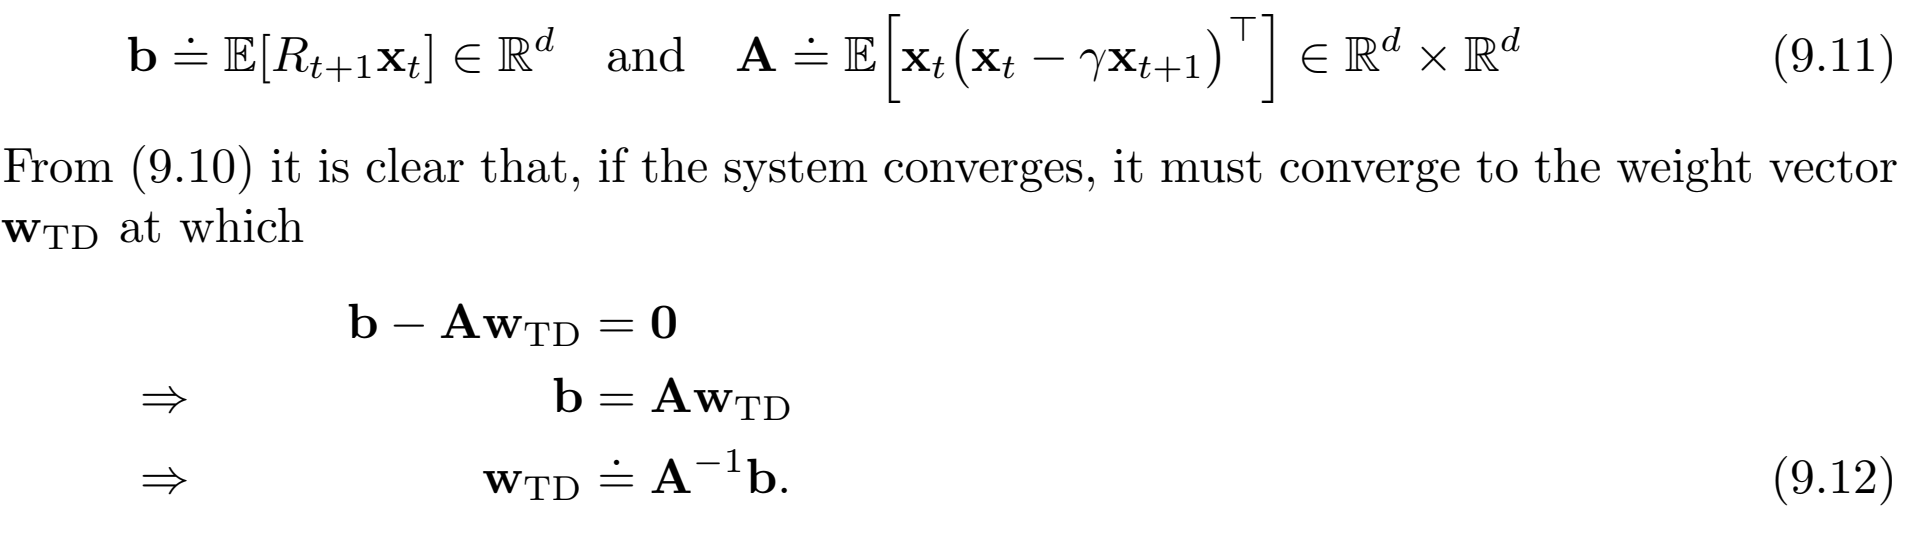

A = zeros(states, states, samples); %pre-initialize A matrix
b = zeros(states, samples); %pre-initialize b vector
for ii = 1:samples %calculate b and A samples and store them along a buffer dimension
    b(:,ii)=r(ii)*x_k(:,ii);
    A(:,:,ii)= x_k(:,ii)*(x_k(:,ii)-gamma*x_k1(:,ii))';
end

% Calculate expection of A and b by averaging the samples
A = mean(A,3);
b = mean(b, 2);


Output estimated parameter vector according to TD fix point

w_TD = inv(A)*b

w_TD =     2.0287
    3.0080
    0.9900


## RLS without Forgetting

P_RLS = eye(states);
w_RLS = [0; 0; 0];

for ii=1:samples
    c = P_RLS*(xi(ii,:)')/(1+xi(ii,:)*P_RLS*xi(ii,:)');
    w_RLS = w_RLS + c*(r(ii) - xi(ii,:)*w_RLS);
    P_RLS = (eye(states)-c*xi(ii,:))*P_RLS;
end
w_RLS

w_RLS =     2.0148
    3.0140
    1.0013


## RLS with Forgetting

P_RLSF = eye(states);
w_RLSF = [0; 0; 0];
lambda = 0.99;

for ii=1:samples
    c = P_RLSF*(xi(ii,:)')/(lambda+xi(ii,:)*P_RLSF*xi(ii,:)');
    w_RLSF = w_RLSF + c*(r(ii) - xi(ii,:)*w_RLSF);
    P_RLSF = (eye(states)-c*xi(ii,:))*P_RLSF/lambda;
end
w_RLSF

w_RLSF =     1.9707
    2.9758
    1.0458


## RLS with Forgetting & Regularization

P_RLSR = eye(states);
w_RLSR = [0; 0; 0];
mu = 0.01;

for ii=1:samples
    P_pred = 1/(1 + mu)*(P_RLSR + eye(states));
    P_RLSR = P_pred - (P_pred*xi(ii,:)'*xi(ii,:)*P_pred)/(1+xi(ii,:)*P_pred*xi(ii,:)');
    w_RLSR = w_RLSR + P_RLSR*xi(ii,:)'*(r(ii) - xi(ii,:)*w_RLSR);
end

w_RLSR

w_RLSR =     1.9079
    3.0599
    1.5738
